clear
load running.mat
Acceleration.time=timeElapsed(Acceleration.Timestamp);
Acc=Acceleration{:,["time", "X" ,"Y" ,"Z"]};
Acc=Acc(Acc(:,1)>10 & Acc(:,1)<20,:);

Acc =    10.0810   -1.1309   -5.9055   -3.4442
   10.1810    1.7037   -6.8518   -1.0926
   10.2810    2.7703  -10.3475   -1.8790
   10.3810   -8.4338  -20.3659    2.8325
   10.4810   -5.1948  -18.7481  -10.8963
   10.5810   -9.0111   -4.1210   -6.0712
   10.6810   -6.9861  -33.4505   -2.3097
   10.7810   13.4644   -2.7966   13.9884
   10.8810    1.6436   -7.3953    3.2480
   10.9810   -7.1357  -28.8924    5.4054


Acc_ =    10.0810    6.9294
   10.1810    7.1445
   10.2810   10.8754
   10.3810   22.2244
   10.4810   22.2981
   10.5810   11.6207
   10.6810   34.2502
   10.7810   19.6160
   10.8810    8.2427
   10.9810   30.2475


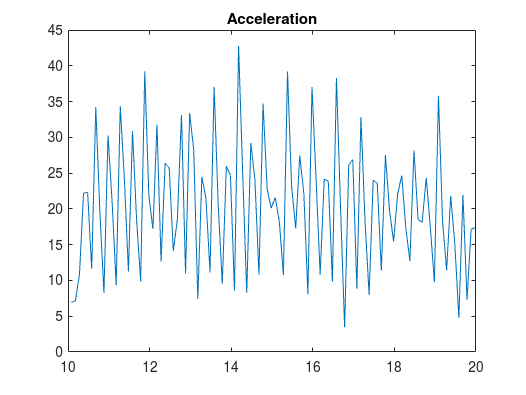

Acc_=[Acc(:,1),sqrt((Acc(:,2)).^2+(Acc(:,3)).^2+(Acc(:,4)).^2)];


[rows,~]=size(Acc_);
high_points=[0 0];
bottom_points=[0 100];
avg_value=mean(Acc_(:,2));

avg_value = 20.4170

flag=1;
top=[0 0];
bottom=[0 100];
for i=1:rows
    if flag==1
        if Acc_(i,2) >avg_value
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        else
            high_points=[high_points; top];
            flag=0;
            top=[0 0];
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        end
    else
        if Acc_(i,2)<=avg_value
            if Acc_(i,2)<bottom(2)
                bottom=Acc_(i,:);
            end
        else
            bottom_points=[bottom_points;bottom];
            flag=1;
            bottom=[0 100];
            if Acc_(i,2)>top(2)
                top=Acc_(i,:);
            end
        end
    end
end
high_points=high_points(2:end,:);

high_points =          0         0
   10.4810   22.2981
   10.6810   34.2502
   10.9810   30.2475
   11.2810   34.3615
   11.5810   30.8507
   11.8810   39.2263
   12.1810   31.8030
   12.3810   26.3795
   12.7810   33.1286


[rows_top,~]=size(high_points);

rows_top = 33

bottom_points=bottom_points(2:end,:);

bottom_points =    10.0810    6.9294
   10.5810   11.6207
   10.8810    8.2427
   11.1810    9.3290
   11.4810   11.2578
   11.7810    9.8666
   12.0810   17.2004
   12.2810   12.6640
   12.5810   14.1329
   12.8810   10.9557


[rows_bot,~]=size(bottom_points);

rows_bot = 32

duration=[];


duration =

     []



step_height=[];


step_height =

     []



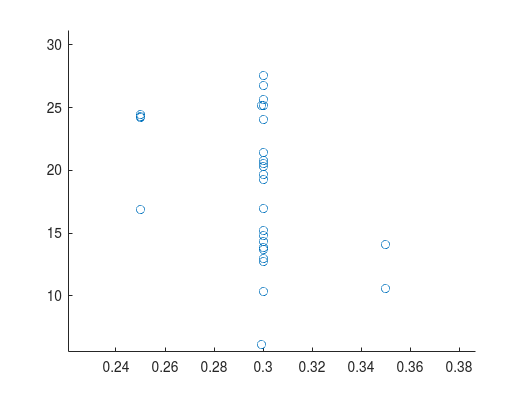

for i=2:rows_top-1
    dur=(-high_points(i-1,1)+high_points(i+1,1))/2;
    height=(high_points(i,2)-bottom_points(i-1,2)+high_points(i,2)-bottom_points(i,2))/2;
    duration=[duration,dur];
    step_height=[step_height, height];
end
duration=duration(2:end)';
step_height=step_height(2:end)';
result3=[duration, step_height]